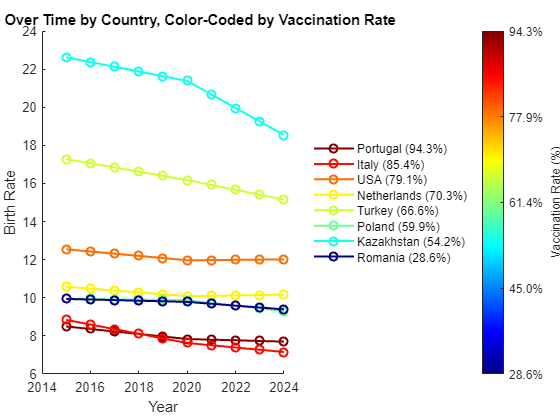

[num, txt, raw] = xlsread('C:\Users\CShort\Documents\GitHub\birth_vax_rate\birth_rates.xlsx');
birth_rates = num(2:end,1:end-1);
vax_rate = num(2:end,end);
countries = txt(2:end,1);
numCountries = length(countries);
years = num(1,1:end-1);

figure;
colormap(jet); % Choose a colormap; 'jet' gives a gradient from blue to red

% Normalize vaccination rates for color mapping
vax_norm = (vax_rate - min(vax_rate)) / (max(vax_rate) - min(vax_rate));
colors = colormap; % Get the colormap matrix
hold on;

% Plot each country's original birth rate data with color based on vaccination rate
for i = 1:numCountries
    % Map each vaccination rate to a color in the colormap
    color_idx = round(vax_norm(i) * (size(colors, 1) - 1)) + 1;
    plot(years, birth_rates(i, :), '-o', 'Color', colors(color_idx, :), 'LineWidth', 1.5, 'DisplayName', sprintf('%s (%.1f%%)', countries{i}, vax_rate(i)));
end

% Customize plot appearance
xlabel('Year');
ylabel('Birth Rate');
title('Birth Rate Over Time by Country, Color-Coded by Vaccination Rate');
legend('show', 'Location', 'eastoutside');
legend boxoff;

% Add a color bar to indicate vaccination rates
c = colorbar;
c.Label.String = 'Vaccination Rate (%)';
c.Ticks = linspace(0, 1, 5); % Adjust ticks for readability
c.TickLabels = arrayfun(@(x) sprintf('%.1f%%', x), linspace(min(vax_rate), max(vax_rate), 5), 'UniformOutput', false);

hold off;

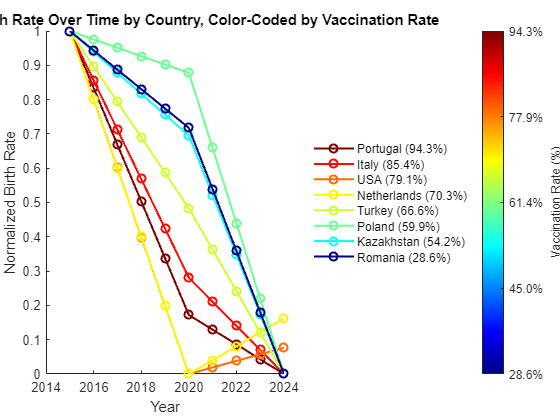

figure;
colormap(jet); % Choose a colormap; 'jet' gives a gradient from blue to red

% Normalize vaccination rates for color mapping
vax_norm = (vax_rate - min(vax_rate)) / (max(vax_rate) - min(vax_rate));
colors = colormap; % Get the colormap matrix
hold on;

% Normalize birth rates for each country and plot
for i = 1:numCountries
    % Normalize birth rates for the current country
    birth_rate_norm = (birth_rates(i, :) - min(birth_rates(i, :))) / (max(birth_rates(i, :)) - min(birth_rates(i, :)));
    
    % Map each vaccination rate to a color in the colormap
    color_idx = round(vax_norm(i) * (size(colors, 1) - 1)) + 1;
    plot(years, birth_rate_norm, '-o', 'Color', colors(color_idx, :), 'LineWidth', 1.5, 'DisplayName', sprintf('%s (%.1f%%)', countries{i}, vax_rate(i)));
end

% Customize plot appearance
xlabel('Year');
ylabel('Normalized Birth Rate');
title('Normalized Birth Rate Over Time by Country, Color-Coded by Vaccination Rate');
legend('show', 'Location', 'eastoutside');
legend boxoff;

% Add a color bar to indicate vaccination rates
c = colorbar;
c.Label.String = 'Vaccination Rate (%)';
c.Ticks = linspace(0, 1, 5); % Adjust ticks for readability
c.TickLabels = arrayfun(@(x) sprintf('%.1f%%', x), linspace(min(vax_rate), max(vax_rate), 5), 'UniformOutput', false);

hold off;